# Experiment 2: Sampling Consistency and Release-Delay Characterization Report

To obtain the delay offset of the Tethered-Release System under various configurations. The main focus is the timing of the release event. We have the following assumptions of the delay of the tethered-release system. 

- The ground truth of release event is when the tether is released. The ground truth can be detected by a sudden drop in the tether tension -  load cell (force sensor) readouts. 

- When using the LiveAmp setuo, the ground truth is acquired by connecting the load cell to the LiveAmp, requiring a wire in addition to the tether connect to the patient.

Based on our setup, there are other approaches of determining the release event besides the force sensor. We design separate sub-experiments to gather and analyze data from them. They are:

- Experiment 2a: Release trigger signal, connects to trigger box that is not on the patient, does not require an additional wire.

- Experiment 2b: Accelerometer signal, LiveAmp on-board sensor, does not require an additional wire.

We used the Lab Streaming Layer (LSL) to setup the multi-sensor recording environment. LSL is advertised to have accurate and consistent sampling up to ms level. We want to confirm this by first analyzing the sampling and timestamp consistency of the recordings from LSL and then investigating the optimal hardware and LSL setup for our experiment and further brain and balance research.

The goal of this experiment is to evaluate the distribution (via observing the spread and statistical measures such as mean and STD) of the release delay of the release trigger signal and accelerometer signal approaches. Based on the fact that balance N1, appearing after the release event, is subcortical and cortical -> 50~150ms after the release -> up to 100 ms wide, we can determine if the sensors can reliably determine the release event.

- Mean: not really any threshold for that as long as the STD is good

- STD: measures the repeatability or jitter of the latency, should be within 10ms to be research practical.

% housekeeping
clear;
clc;

% define working directories
scriptDir = fileparts(matlab.desktop.editor.getActiveFilename); % obtain script path
recordings_folder = "Recordings";
working_folder = fullfile(scriptDir, recordings_folder);
cd(working_folder); % set the working folder to the specified folder

**Note that for the following experiments, the recorded timestamps are in seconds, if no conversion is specified.**

## Experiment 2o: TimeStamps/Sampling Consistency

First we evaluate the sampling consistency of the LSL system. 

Priliminary studies on ActiCHamp data show that the effective sampling intervals (measured by taking the difference between two consecutive timestamps) varies across each recording. There are even a small fraction of the sampling intervals negative, meaning that a later timestamp has a value smaller than the earilier timestamp. As shown in the figure below, the left subplot is the sampling interval for each sampe in the data recording (y axis unit in sec), the right subplot is the distribution of the sampling interval.

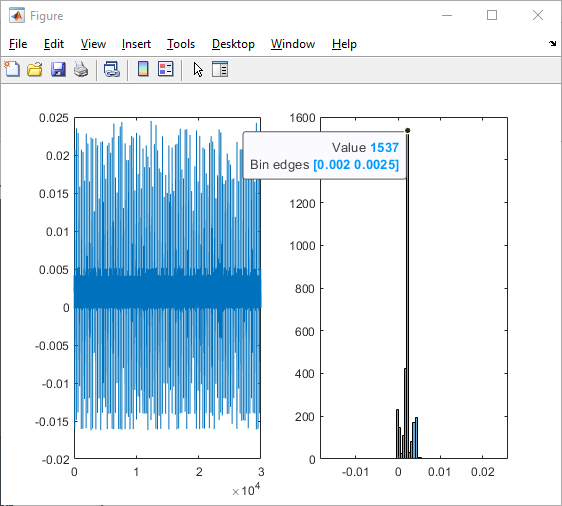

There are many possible sources that cause inconsistent sampling intervals. For instance, it could be caused by the LSL library's inherent nature, it could be caused by the Brain Product's connection program, or it could be caused by my implementation of the LSL-based recorder that retrieves streamed data. Since there are many stages in the signaling pathway, we have to rule them out separately. The stages can be roughly broken down to the sensor stage, the connector stage, and the recorder stage. 

- **The Sensor Stage:** Sensor (microphone) -> Onboard Amplifier -> Windows (COM port, usb bus, driver, etc)

- **The Connector Stage:** Connector Program (Audio Capture for laptop onbard microphone / ActiCHamp Connector for ActiCHamp / LiveAmp Connector for LiveAmp)

- **The Recorder Stage:** Recorder Program (Lab Recorder / MATLAB Script using LSL functions / MATLAB GUI using LSL functions)

The LSL library and tools invole in the connector stage and the recorder stage.

First, we investigate the timestamps consistency of data recordings taken with a different sensor to see if the sensors are the cause of the inconsistent sampling interval. A easy to get sensor is the laptop onboard microphone. By using the Audio Capture app avaliable in the LSL library, we compare the computer onboard microphone and the ActiCHamp setup.

% load data
% MATLAB Script: Audio Capture Data
data_Audio_Script_pull_chunk = load("timestamp_consistency\Audio\Audio_Capture_LSL_0320_1151.mat").stored; % sample pulled using pull_chunk function
data_Audio_Script_pull_sample = load("timestamp_consistency\Audio\Audio_Capture_LSL_0320_1254.mat").stored; % sample pulled using pull_sample function
data_Audio_Script_delay_100 = load("timestamp_consistency\Audio\Audio_Capture_LSL_0320_1317.mat").stored; % sample pulled using pull_chunk function, delay 100ms before each pull
data_Audio_Script_delay_200 = load("timestamp_consistency\Audio\Audio_Capture_LSL_0320_1340.mat").stored; % sample pulled using pull_chunk function, delay 200ms before each pull
data_Audio_Script_delay_500 = load("timestamp_consistency\Audio\Audio_Capture_LSL_0320_1341.mat").stored; % sample pulled using pull_chunk function, delay 500ms before each pull
data_Audio_GUI = table2array(load("timestamp_consistency\Audio\Audio_Capture_GUI_0320_1151.mat").recorded_sample);
data_Audio_labRecorder = load_xdf("timestamp_consistency\Audio\block_default.xdf");
timestamps_Audio_labRecorder = data_Audio_labRecorder{1, 1}.time_stamps;

% MATLAB GUI: ActiCHamp data with weights
data_ActiCHamp_GUI_weights = (table2array(load("Recording_sample_2025_02_25_05_11_22.mat").table_to_save));
marker_ActiCHamp_GUI_weights = (table2array(load("Recording_sample_2025_02_25_05_11_22_markers.mat").table_to_save));
% MATLAB GUI: ActiCHamp data with human subjects
data_ActiCHamp_GUI_humans = (table2array(load("Lean Angles\Lean_09_Feb27_2025_test_3.mat").table_to_save));
marker_ActiCHamp_GUI_humans = (table2array(load("Lean Angles\Lean_09_Feb27_2025_test_3_markers.mat").table_to_save));

### Analysis

First we analyze the audio capture pathway.

#### Audio Capture

The Audio Capture program is setup with the following configurations. Sample rate is set up 8000 Hz, sample size is set to 16 bit. 

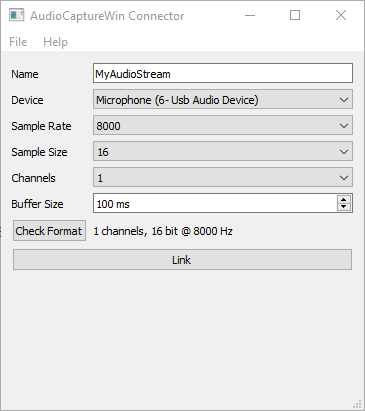

Unfortunely, the Lab Recorder is not compatiable with the sampling frequency of the Audio Capture. So we have to use the LSL function to retrieve data streamed by Audio Capture. The functions are pull_sample() and pull_chunk(). pull_sample() pulls 1 sample for each call and pull_chunk() pulls all new samples since last call for each call. The functions are called in a loop. To minimize the influence of the MATLAB related operations, the other lines in the loop are for storing and displaying the pulled samples. A pause function is called after each pull for testing the frequency of pulling data. My hypothesis is that if data is pulled too fast, it might interfere with the normal functions of the connector app and worsen the timestamp consistency, thus worsening the sampling interval consistency.

**Signal Pathway:**

Sensor (microphone) -> Onboard Amplifier -> Windows -> Connector Program (Audio Capture) -> Recorder (MATLAB Script)

By setting the pause time to 0, 0.1, 0.2, and 0.5 sec (roughly simulating pulling samples immediately, every 100 ms, every 200 ms, and every 500 ms), we can calculate for the mean, STD, and distribution of the sampling interval from each setup. The plots and table shown below are the results.

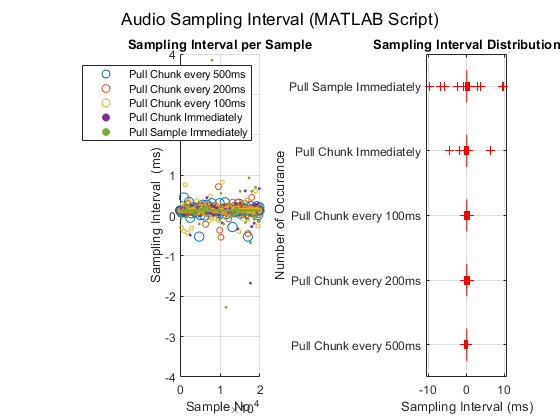

% sort, we should not sort timestamps as the LSL garantees that the samples
% are in monotonically increasing order.
% data_Audio_Script_pull_chunk = sortrows(data_Audio_Script_pull_chunk, 2);
% data_Audio_Script_pull_sample = sortrows(data_Audio_Script_pull_sample, 2);
% data_Audio_Script_delay_100 = sortrows(data_Audio_Script_delay_100, 2);
% data_Audio_Script_delay_200 = sortrows(data_Audio_Script_delay_200, 2);
% data_Audio_Script_delay_500 = sortrows(data_Audio_Script_delay_500, 2);

% sampling intervals of MATLAB Script Recorder powered by LSL
sampling_interval_Audio_script = diff(data_Audio_Script_pull_chunk(2 : 2e4 + 1, 2));
sampling_interval_Audio_script_pull_sample = diff(data_Audio_Script_pull_sample(2 : 2e4 + 1, 2));
sampling_interval_Audio_script_delay_100 = diff(data_Audio_Script_delay_100(2 : 2e4 + 1, 2));
sampling_interval_Audio_script_delay_200 = diff(data_Audio_Script_delay_200(2 : 2e4 + 1, 2));
sampling_interval_Audio_script_delay_500 = diff(data_Audio_Script_delay_500(2 : 2e4 + 1, 2));
sampling_interval_combined = [sampling_interval_Audio_script_delay_500, sampling_interval_Audio_script_delay_200, sampling_interval_Audio_script_delay_100, ...
    sampling_interval_Audio_script, sampling_interval_Audio_script_pull_sample];

% Parameters
str_legend_audio = ["Pull Chunk every 500ms", "Pull Chunk every 200ms", "Pull Chunk every 100ms", "Pull Chunk Immediately", "Pull Sample Immediately"];
% plot
figure;
subplot(1, 2, 1)
hold on
scatter(1 : length(sampling_interval_Audio_script_delay_500), sampling_interval_Audio_script_delay_500 * 1e3, 50)
scatter(1 : length(sampling_interval_Audio_script_delay_200), sampling_interval_Audio_script_delay_200 * 1e3, 20)
scatter(1 : length(sampling_interval_Audio_script_delay_100), sampling_interval_Audio_script_delay_100 * 1e3, 10)
scatter(1 : length(sampling_interval_Audio_script), sampling_interval_Audio_script * 1e3, 5, 'filled')
scatter(1 : length(sampling_interval_Audio_script_pull_sample), sampling_interval_Audio_script_pull_sample * 1e3, 5, 'filled')
grid on
hold off
xlim([0, 2e4])
ylim([-4, 4])
xlabel("Sample No.")
ylabel("Sampling Interval  (ms)")
legend(str_legend_audio)
title("Sampling Interval per Sample")
subplot(1, 2, 2)
boxplot(sampling_interval_combined * 1e3, 'Labels', str_legend_audio, "Orientation", "horizontal")
xlabel("Sampling Interval (ms)")
ylabel("Number of Occurance")
grid on
title("Sampling Interval Distribution")
sgtitle("Audio Sampling Interval (MATLAB Script)")

In the figure shown above, the left subplot are the sampling intervals from each experiment config, using either pull_sample() and pull_chunk(), the majority of the sampling interval is located 0.125 ms, corresponds to the 8000 Hz sampling rate. However, if we look at the box plot for each setup, the pull sampling immediately and pull chunk immediately configs have more outliers (marked by the red plus sign) that could be up to 10 ms away from the mean.

**Mean and STD of the MATLAB Script at different configurations:**

The mean and STD of the different configs are shown below, we can clearly see that pulling immediately resulted in significantly worse standard deviations. 

mean_500 = mean(sampling_interval_Audio_script_delay_500);
std_500 = std(sampling_interval_Audio_script_delay_500);
mean_200 = mean(sampling_interval_Audio_script_delay_200);
std_200 = std(sampling_interval_Audio_script_delay_200);
mean_100 = mean(sampling_interval_Audio_script_delay_100);
std_100 = std(sampling_interval_Audio_script_delay_100);
mean_0 = mean(sampling_interval_Audio_script);
std_0 = std(sampling_interval_Audio_script);
mean_pull_sample = mean(sampling_interval_Audio_script_pull_sample);
std_pull_sample = std(sampling_interval_Audio_script_pull_sample);

means = [mean_500, mean_200, mean_100, mean_0, mean_pull_sample] .* 1e3;
stds = [std_500, std_200, std_100, std_0, std_pull_sample] .* 1e3;
T = table(str_legend_audio', means', stds', 'VariableNames', {'Setup', 'Mean (ms)', 'Standard Deviation (ms)'})

T = 5×3 table
              Setup              Mean (ms)    Standard Deviation (ms)
    _________________________    _________    _______________________

    "Pull Chunk every 500ms"      0.12499            0.0088171       
    "Pull Chunk every 200ms"      0.12501            0.0099725       
    "Pull Chunk every 100ms"      0.12497             0.012945       
    "Pull Chunk Immediately"        0.125             0.057159       
    "Pull Sample Immediately"     0.12498              0.13896       


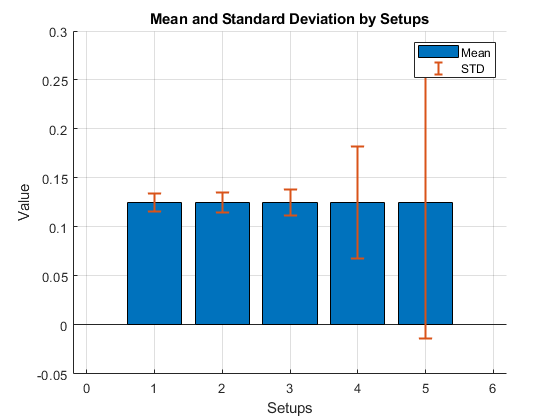


figure
hold on
bar(means, 'FaceColor', 'flat')
errorbar(1 : 5, means, stds, 'LineStyle', 'none', 'LineWidth', 1.5, 'CapSize', 10)
ylabel('Value')
xlabel('Setups')
legend("Mean", "STD")
title('Mean and Standard Deviation by Setups');
grid on;
hold off;

Setups 1 to 5 corresponds to -> "Pull Chunk every 500ms", "Pull Chunk every 200ms", "Pull Chunk every 100ms", "Pull Chunk Immediately", "Pull Sample Immediately"

**Comments:** The above results have shown that the sensor stage is probably not the source of the inconsistent sampling intervals. That's because the same problem persist for different sensors. The use of the LSL function does influence the sampling intervals. Next, we switch back to the ActiCHamp system to test for the recorder stage in this pathway.

% sampling intervals of MATLAB GUI and Lab Recorder powered by LSL
% sampling_interval_Audio_GUI = diff(data_Audio_GUI(2 : end, 1));
% sampling_interval_Audio_Lab = diff(timestamps_ActiCHamp_labRecorder);
% % plot
% figure;
% subplot(1, 2, 1)
% hold on
% scatter(1 : length(sampling_interval_Audio_GUI), sampling_interval_Audio_GUI * 1e3)
% scatter(1 : length(sampling_interval_Audio_Lab), sampling_interval_Audio_Lab * 1e3, 10, 'filled')
% xlim([0, 1e3])
% legend('MATLAB GUI', 'Lab Recorder (auto jitter removal)')
% xlabel("Sample No.")
% ylabel("Sampling Interval  (ms)")
% title("Sampling Interval per Sample")
% subplot(1, 2, 2)
% histogram(sampling_interval_Audio_GUI * 1e3, 20, 'EdgeColor', 'none')
% xlabel("Sampling Interval (ms)")
% ylabel("Number of Occurance")
% title("Sampling Interval Distribution")
% sgtitle("Audio Sampling Interval (MATLAB GUI vs. Lab Recorder)")
% Mean and STD of MATLAB GUI and Lab Recorder:
% mean(sampling_interval_Audio_GUI), std(sampling_interval_Audio_GUI)
% mean(sampling_interval_Audio_Lab), std(sampling_interval_Audio_Lab)

#### ActiCHamp

Here, we look at the ActiCHamp data recorded via the MATLAB GUI (which also uses pull_chunk in a very large loop) and Lab Recorder. When loading the Lab Recorder recorded data to MATLAB workspace via load_xdf(), we have a setting 'HandleJitterRemoval' set to true by default. This setting automatically remove jitter by repositioning the timestamps in an ascending order. We tested for both the jitter removal on and off when loading the xdf data recorded by Lab Recorder. 

**Signal Pathway:**

Sensor (EEG/Conditioned Force) -> Amplifier (ActiCHamp/LiveAmp) -> Windows  (USB Wired ActiCHamp /  Bluetooth Wireless LiveAmp) -> Connector Program (ActiCHamp Connector / LiveAmp Connector) -> Recorder Program (Lab Recorder / MATLAB Script / MATLAB GUI)

% load data
% Lab Recorder: ActiCHamp data
lab_recording_full_path = fullfile(working_folder, "timestamp_consistency", "block_lab_recorder_lsl_32eeg_8aux_10000_20_500.xdf");
data_ActiCHamp_labRecorder = load_xdf(lab_recording_full_path, 'HandleJitterRemoval', 1);
data_ActiCHamp_labRecorder_0 = load_xdf(lab_recording_full_path, 'HandleJitterRemoval', 0);
timestamps_ActiCHamp_labRecorder = (data_ActiCHamp_labRecorder{1, 1}.time_stamps); % we should not sort timestamps
timestamps_ActiCHamp_labRecorder_0 = (data_ActiCHamp_labRecorder_0{1, 1}.time_stamps); % for the reason mentioned above
raw_de_jittered_diff = (timestamps_ActiCHamp_labRecorder_0(2 : 10000) - timestamps_ActiCHamp_labRecorder(2 : 10000));

% check for periodicity
sample_duration = timestamps_ActiCHamp_labRecorder_0(10000) - timestamps_ActiCHamp_labRecorder_0(2) % in seconds

sample_duration = 19.9967

[~, locs] = findpeaks(-raw_de_jittered_diff, "MinPeakHeight", 5 * 1e-3);
num_negative_peaks = length(locs)

num_negative_peaks = 38

nominal_negative_peak_periodicity = (10000 - 1) / num_negative_peaks % in number of samples

nominal_negative_peak_periodicity = 263.1316

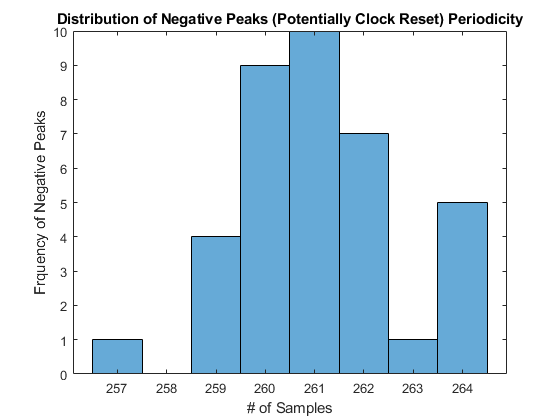

% actual periodicity
figure
histogram(diff(locs))
xlabel("# of Samples")
ylabel("Frquency of Negative Peaks")
title("Distribution of Negative Peaks (Potentially Clock Reset) Periodicity")

% sampling intervals of MATLAB GUI and Lab Recorder powered by LSL
sampling_interval_EEG_GUI = diff(data_ActiCHamp_GUI_weights(2 : end, 1));
sampling_interval_EEG_Lab = diff(timestamps_ActiCHamp_labRecorder);
sampling_interval_EEG_Lab_0 = diff(timestamps_ActiCHamp_labRecorder_0); % no jitter removal
% sampling_interval_lab_recorder_2_3000 = sampling_interval_lab_recorder(2 : 3000);
str_legend_Lab_EEG = ["MATLAB GUI", "Lab Recorder JitterRemoval Off", "Lab Recorder JitterRemoval On", "Diff of JitterRemoval On/Off"]; % 
% plot
figure;
subplot(1, 2, 1)
hold on
scatter(2 : 10000, sampling_interval_EEG_GUI(2 : 10000) * 1e3) % when display, convert to ms
scatter(2 : 10000, sampling_interval_EEG_Lab_0(2 : 10000) * 1e3)
scatter(2 : 10000, sampling_interval_EEG_Lab(2 : 10000) * 1e3)
% plot(2 : 10000, raw_de_jittered_diff * 1e3)
hold off
grid on
legend(str_legend_Lab_EEG)

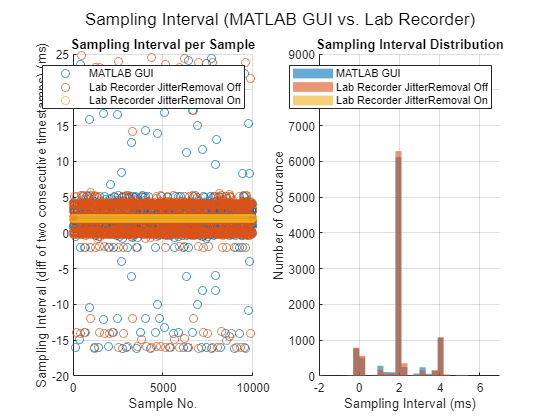

xlabel("Sample No.")
ylabel("Sampling Interval (diff of two consecutive timestamps) (ms)")
title("Sampling Interval per Sample")
subplot(1, 2, 2)
hold on
histogram(sampling_interval_EEG_GUI(2 : 10000) * 1e3, 'EdgeColor', 'none') % when display, convert to ms
histogram(sampling_interval_EEG_Lab_0(2 : 10000) * 1e3, 'EdgeColor', 'none')
histogram(sampling_interval_EEG_Lab(2 : 10000) * 1e3, 'EdgeColor', 'none') % "BinLimits", [2.00002510, 2.00002514]
hold off
legend(str_legend_Lab_EEG(1 : 3))
xlim([-2, 7])
xlabel("Sampling Interval (ms)")
ylabel("Number of Occurance")
grid on
title("Sampling Interval Distribution")
sgtitle("Sampling Interval (MATLAB GUI vs. Lab Recorder)") % ActiCHamp 

In the figure shown above, the left subplot is the sampling intervals for each condition. The yellow circles indicate the jitter removed Lab Recorder recording. They located exactly at the 2 ms position without any outliers. However, the same Lab Recorder recording loaded without jitter removal, shown as the orange circles, are nearly as inconsistent as the MATLAB GUI recordings indicated by the blue circles. However, the orange circles are located mainly at the 0, 2, and 4 ms positions with outliers located near the extremeties (25 and -15 ms). Where as the outliers for the blue circles are more evenly distributed. The left subplot is the distribution of the sampling intervals for each condition. The distributions from the MATLAB GUI recording and the Lab Recorder recording without jitter removal are very similar.

**Mean and STD of MATLAB GUI and Lab Recorder:**

The mean sampling interval for both the MATLAB GUI and Lab Recorder are 0.0020 s = 2 ms which agrees with the 500Hz nominal sampling rate of the ActiCHamp Connector program. The sampling interval STDs from the MATLAB GUI recordings and that of the Lab Recorder (without jitter removal) are not different either.

means_1 = [mean(sampling_interval_EEG_GUI(2 : 10000)), mean(sampling_interval_EEG_Lab_0), mean(sampling_interval_EEG_Lab)] * 1e3; % converted to ms
stds_1 = [std(sampling_interval_EEG_GUI(2 : 10000)), std(sampling_interval_EEG_Lab_0), std(sampling_interval_EEG_Lab)] * 1e3;
T = table(str_legend_Lab_EEG(1 : end - 1)', means_1', stds_1', 'VariableNames', {'Setup', 'Mean (ms)', 'Standard Deviation (ms)'})

T = 3×3 table
                 Setup                  Mean (ms)    Standard Deviation (ms)
    ________________________________    _________    _______________________

    "MATLAB GUI"                         2.0001                1.8898       
    "Lab Recorder JitterRemoval Off"          2                1.9523       
    "Lab Recorder JitterRemoval On"           2            4.3485e-08       


**Comments:** The implementation of retrieving data from LSL EEG Streams in the MATLAB GUI could be suboptimal. However, the inconsistent sampling intervals exist for both the MATLAB GUI, MATLAB Script, and the Lab Recorder. Thus, the inconsistency possibly does not come from the recorder stage either. Changing implementation (shown by pausing differently in the previous section) might help improve the consistency, but cannot solve the problem entirely. The sampling interval inconsistency could be an LSL inherent problem since the timestamps are generated. A good news is that LSL don't change the order of the data samples and don't miss samples under normal network conditions. We are expected to get all the data samples even though the timestamps could be inconsistent. 

#### Function Generator

The result of Experiment 2o-1 demonstrated that the timestamps recorded by LSL are inconsistent, disregarding the choice of the sensors or recorders. The true source of the sampling inconsistency is still unknown. 

Based on the LSL documents/guides,

- The LSL system will not change the order of the sampled data. 

- The LSL system will not change the value of the sampled data, only the timestamps.

- The LSL system only considers the timestamps of the data when performing de-jittering or clock sync.

- The LSL system might have irregular sampling interval due to multiple reasons, including intrinsic device delay, periodic clock drift sync, and jitter.

- The LSL system interpolate the data based on the raw timestamps by considering the nominal sampling rate and any identified gaps in the recording. 

- The dejittering algorithm is in load_xdf() and is listed on the side. Note that this function only changes timestamps, not values. This function does not reorder sample sequence.

To experimentally determine the sampling order and sampling interval consistency, we design this experiment. In this experiment, we use a function generator to generate periodic triangular wave with maximum acceptable slope magnitude. 

Based on the ActiCHamp and LiveAmp limitations, the triangular wave is configured as follows:

- Frequency (Hz): 25 Hz, 12.5 Hz, 6.25 Hz, 3.125 Hz

- Amplitude (peak-to-peak): 8V, 7.8~7.9 V read by the oscilloscope

- Duty Cycle: 50%

- Offset: 0 V

- Attenuation: 0dB

% load data, suffix naming scheme, 1 for on 0 for off.
% load data wt default settings: 
% 1st digit: HandleJitterRemoval On, 1
% 2nd digit: HandleClockSynchronization On, 1
signal_25p000Hz_11_xdf = load_xdf("timestamp_consistency\timestamp_consistency_triangular_wave\Signal_Vpp8_25Hz_AUX1_1split1.xdf");
signal_12p500Hz_11_xdf = load_xdf("timestamp_consistency\timestamp_consistency_triangular_wave\Signal_Vpp8_12p5Hz_AUX1_1split1.xdf");
signal_06p250Hz_11_xdf = load_xdf("timestamp_consistency\timestamp_consistency_triangular_wave\Signal_Vpp8_6p25Hz_AUX1_1split1.xdf");
signal_03p125Hz_11_xdf = load_xdf("timestamp_consistency\timestamp_consistency_triangular_wave\Signal_Vpp8_3p125Hz_AUX1_1split1.xdf");
noise_25p000Hz_11_xdf = load_xdf("timestamp_consistency\timestamp_consistency_triangular_wave\Noise_Vpp8_25Hz_AUX1_1split1.xdf");
% 01
signal_25p000Hz_01_xdf = load_xdf("timestamp_consistency\timestamp_consistency_triangular_wave\Signal_Vpp8_25Hz_AUX1_1split1.xdf", 'HandleJitterRemoval', 0);
signal_12p500Hz_01_xdf = load_xdf("timestamp_consistency\timestamp_consistency_triangular_wave\Signal_Vpp8_12p5Hz_AUX1_1split1.xdf", 'HandleJitterRemoval', 0);
signal_06p250Hz_01_xdf = load_xdf("timestamp_consistency\timestamp_consistency_triangular_wave\Signal_Vpp8_6p25Hz_AUX1_1split1.xdf", 'HandleJitterRemoval', 0);
signal_03p125Hz_01_xdf = load_xdf("timestamp_consistency\timestamp_consistency_triangular_wave\Signal_Vpp8_3p125Hz_AUX1_1split1.xdf", 'HandleJitterRemoval', 0);
noise_25p000Hz_01_xdf = load_xdf("timestamp_consistency\timestamp_consistency_triangular_wave\Noise_Vpp8_25Hz_AUX1_1split1.xdf", 'HandleJitterRemoval', 0);
% 00
signal_25p000Hz_00_xdf = load_xdf("timestamp_consistency\timestamp_consistency_triangular_wave\Signal_Vpp8_25Hz_AUX1_1split1.xdf", 'HandleJitterRemoval', 0, 'HandleClockSynchronization', 0);
signal_12p500Hz_00_xdf = load_xdf("timestamp_consistency\timestamp_consistency_triangular_wave\Signal_Vpp8_12p5Hz_AUX1_1split1.xdf", 'HandleJitterRemoval', 0, 'HandleClockSynchronization', 0);
signal_06p250Hz_00_xdf = load_xdf("timestamp_consistency\timestamp_consistency_triangular_wave\Signal_Vpp8_6p25Hz_AUX1_1split1.xdf", 'HandleJitterRemoval', 0, 'HandleClockSynchronization', 0);
signal_03p125Hz_00_xdf = load_xdf("timestamp_consistency\timestamp_consistency_triangular_wave\Signal_Vpp8_3p125Hz_AUX1_1split1.xdf", 'HandleJitterRemoval', 0, 'HandleClockSynchronization', 0);
noise_25p000Hz_00_xdf = load_xdf("timestamp_consistency\timestamp_consistency_triangular_wave\Noise_Vpp8_25Hz_AUX1_1split1.xdf", 'HandleJitterRemoval', 0, 'HandleClockSynchronization', 0);

% Parameters
channel_sig = 33; % corresponds to AUX 1
str_legend_signal = ["Signal JitterRemoval Off, ClockSync Off", "Signal JitterRemoval Off, ClockSync On", "Signal JitterRemoval On, ClockSync On", "Noise"];
display_window = 500 : 600; % 20000 samples -> around 50 samples / 500 Hz = 0.1 sec
binEdges_25Hz = (1 : 0.2 : 8) * 1e8; % 25 Hz, Vpp = 8V, slope = 8V / (0.5 * 0.04 s) = 
binEdges_12p5Hz = binEdges_25Hz / 2;
binEdges_6p25Hz = binEdges_12p5Hz / 2;
binEdges_3p125Hz = binEdges_6p25Hz / 2;

% format data
% we need both the timestamps and time series to determine sampling
% consistency
signal_25p000Hz_11 = [signal_25p000Hz_11_xdf{1, 3}.time_stamps.', double(signal_25p000Hz_11_xdf{1, 3}.time_series(channel_sig, :).')];
signal_12p500Hz_11 = [signal_12p500Hz_11_xdf{1, 3}.time_stamps.', double(signal_12p500Hz_11_xdf{1, 3}.time_series(channel_sig, :).')];
signal_06p250Hz_11 = [signal_06p250Hz_11_xdf{1, 3}.time_stamps.', double(signal_06p250Hz_11_xdf{1, 3}.time_series(channel_sig, :).')];
signal_03p125Hz_11 = [signal_03p125Hz_11_xdf{1, 3}.time_stamps.', double(signal_03p125Hz_11_xdf{1, 3}.time_series(channel_sig, :).')];
noise_25p000Hz_11 = [noise_25p000Hz_11_xdf{1, 3}.time_stamps.', double(noise_25p000Hz_11_xdf{1, 3}.time_series(channel_sig, :).')];

signal_25p000Hz_01 = [signal_25p000Hz_01_xdf{1, 3}.time_stamps.', double(signal_25p000Hz_01_xdf{1, 3}.time_series(channel_sig, :).')];
signal_12p500Hz_01 = [signal_12p500Hz_01_xdf{1, 3}.time_stamps.', double(signal_12p500Hz_01_xdf{1, 3}.time_series(channel_sig, :).')];
signal_06p250Hz_01 = [signal_06p250Hz_01_xdf{1, 3}.time_stamps.', double(signal_06p250Hz_01_xdf{1, 3}.time_series(channel_sig, :).')];
signal_03p125Hz_01 = [signal_03p125Hz_01_xdf{1, 3}.time_stamps.', double(signal_03p125Hz_01_xdf{1, 3}.time_series(channel_sig, :).')];
noise_25p000Hz_01 = [noise_25p000Hz_01_xdf{1, 3}.time_stamps.', double(noise_25p000Hz_01_xdf{1, 3}.time_series(channel_sig, :).')];


signal_25p000Hz_00 = [signal_25p000Hz_00_xdf{1, 3}.time_stamps.', double(signal_25p000Hz_00_xdf{1, 3}.time_series(channel_sig, :).')];
signal_12p500Hz_00 = [signal_12p500Hz_00_xdf{1, 3}.time_stamps.', double(signal_12p500Hz_00_xdf{1, 3}.time_series(channel_sig, :).')];
signal_06p250Hz_00 = [signal_06p250Hz_00_xdf{1, 3}.time_stamps.', double(signal_06p250Hz_00_xdf{1, 3}.time_series(channel_sig, :).')];
signal_03p125Hz_00 = [signal_03p125Hz_00_xdf{1, 3}.time_stamps.', double(signal_03p125Hz_00_xdf{1, 3}.time_series(channel_sig, :).')];
noise_25p000Hz_00 = [noise_25p000Hz_00_xdf{1, 3}.time_stamps.', double(noise_25p000Hz_00_xdf{1, 3}.time_series(channel_sig, :).')];


Now we obtain the slope of the sampled signals.

We have the following understandings of the sampled signals:

- If the signal is sampled with consistent and uniform sampling intervals by the ActiCHamp or LiveAmp, but the timestamps are inconsistently generated by the LSL when the sampled signal reaches the LSL connector program, the calculated signal slope from the raw signal will have a wider distribution than the signal slope from the dejittered signal. And we should trust and use the dejittered signal.

- If the signal is sampled with inconsistent sampling intervals by the whole ActiCHamp/LiveAmp - LSL system, the calculated signal slope from the raw signal will have a narrower distribution than the signal slope from the dejittered signal. And we should not use the dejittered signal. And LSL is not to be trusted.

- If LSL actually re-orderes signals or results in non-monotonical timestamps during timestamps generation or dejittering stages. We can see these non-monotonical instances on the plot of the sampled signal. And LSL is not to be trusted.

% slopes
% obtain the slope (via numerical differentiation) of the recordings assuming a constant sampling rate.
% histogram(abs(diff(signal_25p000Hz_00(:, 2))), binEdges_25Hz)
slope_signal_25p000Hz_01 = abs(gradient(signal_25p000Hz_01(:, 2)) ./ gradient(signal_25p000Hz_01(:, 1)));
slope_signal_25p000Hz_11 = abs(gradient(signal_25p000Hz_11(:, 2)) ./ gradient(signal_25p000Hz_11(:, 1)));

slope_signal_12p500Hz_01 = abs(gradient(signal_12p500Hz_01(:, 2)) ./ gradient(signal_12p500Hz_01(:, 1)));
slope_signal_12p500Hz_11 = abs(gradient(signal_12p500Hz_11(:, 2)) ./ gradient(signal_12p500Hz_11(:, 1)));

slope_signal_06p250Hz_01 = abs(gradient(signal_06p250Hz_01(:, 2)) ./ gradient(signal_06p250Hz_01(:, 1)));
slope_signal_06p250Hz_11 = abs(gradient(signal_06p250Hz_11(:, 2)) ./ gradient(signal_06p250Hz_11(:, 1)));

slope_signal_03p125Hz_01 = abs(gradient(signal_03p125Hz_01(:, 2)) ./ gradient(signal_03p125Hz_01(:, 1)));
slope_signal_03p125Hz_11 = abs(gradient(signal_03p125Hz_11(:, 2)) ./ gradient(signal_03p125Hz_11(:, 1)));

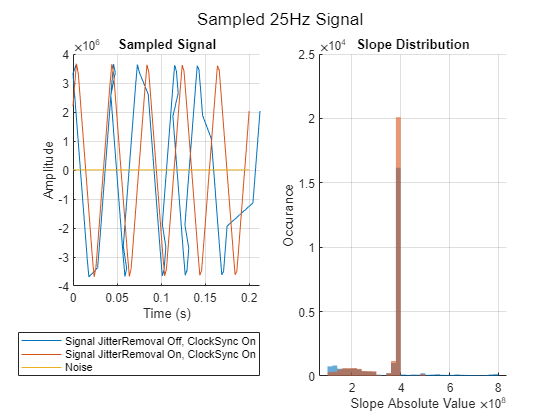

% plot
% 25 Hz
figure
% subplot(2, 2, [1 3])
subplot(1, 2, 1)
hold on
% plot(signal_25p000Hz_00(display_window, 1) - signal_25p000Hz_00(display_window(1), 1), signal_25p000Hz_00(display_window, 2))
plot(signal_25p000Hz_01(display_window, 1) - signal_25p000Hz_01(display_window(1), 1), signal_25p000Hz_01(display_window, 2))
plot(signal_25p000Hz_11(display_window, 1) - signal_25p000Hz_11(display_window(1), 1), signal_25p000Hz_11(display_window, 2))
plot(noise_25p000Hz_11(display_window, 1) - noise_25p000Hz_11(display_window(1), 1), noise_25p000Hz_11(display_window, 2))
hold off
grid on
xlabel("Time (s)")
ylabel("Amplitude")
legend(str_legend_signal(2 : end), "Location", "southoutside")
title("Sampled Signal")
% subplot(2, 2, 2)
subplot(1, 2, 2)
hold on
histogram(slope_signal_25p000Hz_01, binEdges_25Hz, "EdgeColor", "none")
histogram(slope_signal_25p000Hz_11, binEdges_25Hz, "EdgeColor", "none")
% histogram(abs(diff(noise_25p000Hz_11(:, 2))), binEdges_25Hz)
hold off
grid on
xlabel("Slope Absolute Value")
ylabel("Occurance")
title("Slope Distribution")
sgtitle("Sampled 25Hz Signal")

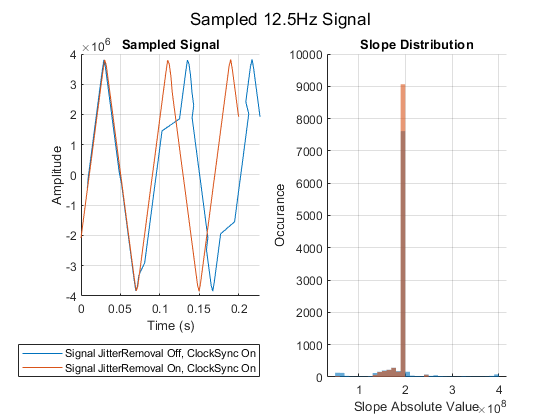

% 12.5 Hz
figure
subplot(1, 2, 1)
hold on
plot(signal_12p500Hz_01(display_window, 1) - signal_12p500Hz_01(display_window(1), 1), signal_12p500Hz_01(display_window, 2))
plot(signal_12p500Hz_11(display_window, 1) - signal_12p500Hz_11(display_window(1), 1), signal_12p500Hz_11(display_window, 2))
% plot(noise_12p500Hz_11(display_window, 1) - noise_12p500Hz_11(display_window(1), 1), noise_12p500Hz_11(display_window, 2))
hold off
grid on
xlabel("Time (s)")
ylabel("Amplitude")
legend(str_legend_signal(2 : end - 1), "Location", "southoutside")
title("Sampled Signal")

subplot(1, 2, 2)
hold on
histogram(slope_signal_12p500Hz_01, binEdges_12p5Hz, "EdgeColor", "none")
histogram(slope_signal_12p500Hz_11, binEdges_12p5Hz, "EdgeColor", "none")
% histogram(abs(diff(noise_25p000Hz_11(:, 2))), binEdges_25Hz)
hold off
grid on
xlabel("Slope Absolute Value")
ylabel("Occurance")
title("Slope Distribution")
sgtitle("Sampled 12.5Hz Signal")

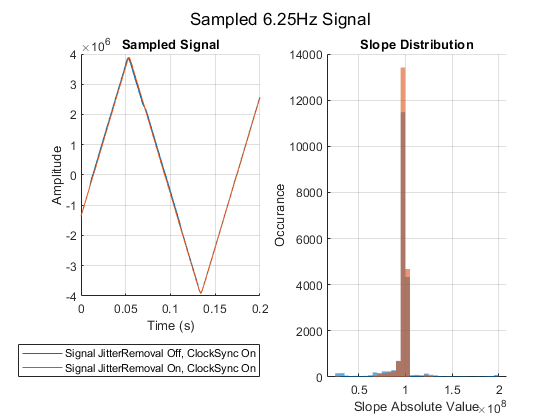

% 6.25 Hz
figure
subplot(1, 2, 1)
hold on
plot(signal_06p250Hz_01(display_window, 1) - signal_06p250Hz_01(display_window(1), 1), signal_06p250Hz_01(display_window, 2))
plot(signal_06p250Hz_11(display_window, 1) - signal_06p250Hz_11(display_window(1), 1), signal_06p250Hz_11(display_window, 2))
hold off
grid on
xlabel("Time (s)")
ylabel("Amplitude")
legend(str_legend_signal(2 : end - 1), "Location", "southoutside")
title("Sampled Signal")

subplot(1, 2, 2)
hold on
histogram(slope_signal_06p250Hz_01, binEdges_6p25Hz, "EdgeColor", "none")
histogram(slope_signal_06p250Hz_11, binEdges_6p25Hz, "EdgeColor", "none")
hold off
grid on
xlabel("Slope Absolute Value")
ylabel("Occurance")
title("Slope Distribution")
sgtitle("Sampled 6.25Hz Signal")

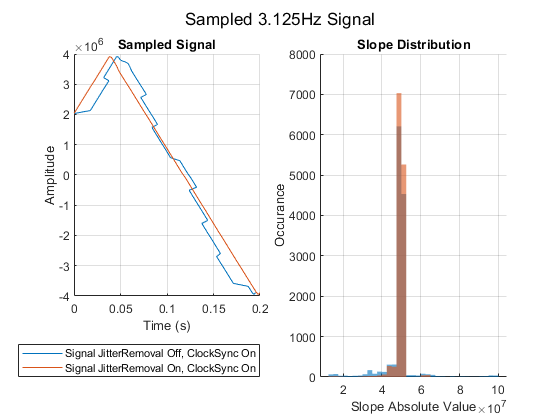

% 3.125 Hz
figure
subplot(1, 2, 1)
hold on
plot(signal_03p125Hz_01(display_window, 1) - signal_03p125Hz_01(display_window(1), 1), signal_03p125Hz_01(display_window, 2))
plot(signal_03p125Hz_11(display_window, 1) - signal_03p125Hz_11(display_window(1), 1), signal_03p125Hz_11(display_window, 2))
hold off
grid on
xlabel("Time (s)")
ylabel("Amplitude")
legend(str_legend_signal(2 : end - 1), "Location", "southoutside")
title("Sampled Signal")

subplot(1, 2, 2)
hold on
histogram(slope_signal_03p125Hz_01, binEdges_3p125Hz, "EdgeColor", "none")
histogram(slope_signal_03p125Hz_11, binEdges_3p125Hz, "EdgeColor", "none")
hold off
grid on
xlabel("Slope Absolute Value")
ylabel("Occurance")
title("Slope Distribution")
sgtitle("Sampled 3.125Hz Signal")

If we calculate and plot the mean and STD of the signal slope with 'HandleJitterRemoval' On and Off. We have:

% calculate mean and STD of the slopes
means_slope_jitterRemoval_On = [mean(slope_signal_25p000Hz_11), mean(slope_signal_12p500Hz_11), mean(slope_signal_06p250Hz_11), ...
    mean(slope_signal_03p125Hz_11)];
means_slope_jitterRemoval_Off = [mean(slope_signal_25p000Hz_01), mean(slope_signal_12p500Hz_01), mean(slope_signal_06p250Hz_01), ...
    mean(slope_signal_03p125Hz_01)];
std_slope_jitterRemoval_On = [std(slope_signal_25p000Hz_11), std(slope_signal_12p500Hz_11), std(slope_signal_06p250Hz_11), ...
    std(slope_signal_03p125Hz_11)];
std_slope_jitterRemoval_Off = [std(slope_signal_25p000Hz_01), std(slope_signal_12p500Hz_01), std(slope_signal_06p250Hz_01), ...
    std(slope_signal_03p125Hz_01)];
T3 = table(["25 Hz", "12.5 Hz", "6.25 Hz", "3.125 Hz"]', ...
    means_slope_jitterRemoval_Off', means_slope_jitterRemoval_On', ...
    std_slope_jitterRemoval_Off', std_slope_jitterRemoval_On', ...
    'VariableNames', {'Signal Frequency (Hz)', 'Mean (Off)', 'Mean (On)', 'STD (Off)', 'STD (On)'})

T3 = 4×5 table
    Signal Frequency (Hz)    Mean (Off)    Mean (On)     STD (Off)      STD (On) 
    _____________________    __________    __________    __________    __________

         "25 Hz"             4.2788e+08    3.5253e+08    1.9701e+09    8.8913e+07
         "12.5 Hz"           1.0799e+09    1.8628e+08    5.4133e+10    3.9095e+07
         "6.25 Hz"           2.0496e+08    9.6193e+07    5.6221e+09    1.4266e+07
         "3.125 Hz"          2.0281e+08    4.8899e+07    6.2476e+09     5.119e+06


**Comments:** The results shows that the assumption of LSL dejittering function, the sampling interval of the ActiCHamp sensors are reliable/consistent, is valid. We should enable the 'HandleJitterRemoval' feature of load_xdf() to ensure data quality. Besides, we should check the "EEG Channel" box under the LSL Trigger Output Style to ensure that the trigger outputs can also be dejittered by the load_xdf().

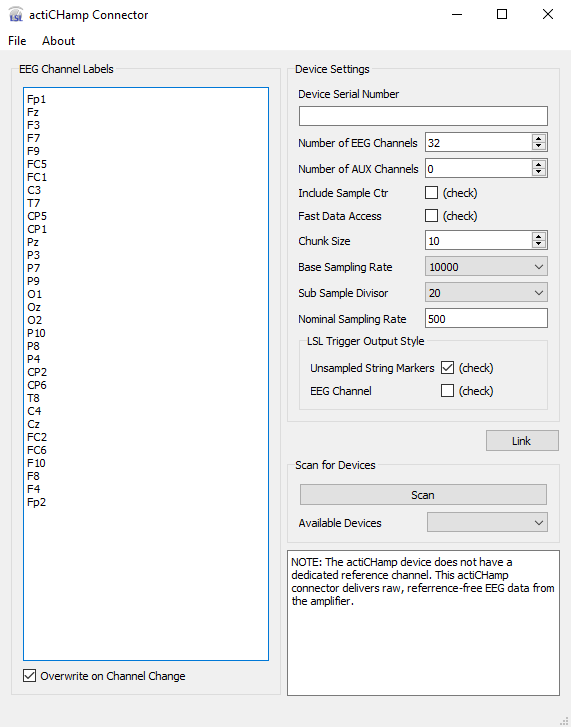

### Conclusion

The sampling inconsistency could be an inherent nature of the LSL system in the connector stage, when the timestamps are generated. But as long as the physical sensor system is reliable, we can trust the auto jitter removal of the LSL system. Given all the above analysis, we should still prioritize the Lab Recorder for data recordings to ensure timestamp consistency as we can perfrom jitter removal and it is the most supported by the Brain Products. For all the subsequent experiments except the 2a Weight vs. Human Subject, we will use the Lab Recorder for recording.

## Experiment 2a: Trigger Button vs. Load Cell (Force Sensor)

Here we look at how well the trigger button signal can be used to replace the force sensor signal in detecting the release event onset. The trigger button is connected to the Trigger Box and is a marker signal. For each release, the trigger button is pressed and released. When the button is pressed, the relay on the metal plate connects and drive the solenoid to trigger the bow release. Thus, the main delay comes from the electro and mechanical structure of the tethered release system, while a small portion of the delay could come from the hardware of the Trigger Box and the ActiCHamp. We measure the sum of two differences here.

### Analysis

#### Weight vs. Human Subject (ActiCHamp, recorded via MATLAB GUI)

First, we look at a few release trials taken by the MALAB GUI, the GUI uses pull_chunk() in a very large loop (the other task for each loop includes updating the plots, checking status of each user input, saving the new data to workspace, etc). The exact time for each loop is not investigated but could be around 500 to 1000 ms. 

Below are some basic information of the recording:

% Parameters
Ts_mean = mean(sampling_interval_EEG_GUI); % mean sampling interval, nominal sampling interval from the ActiCHamp LSL program -> 500Hz -> 0.0020 s
fs_nominal = 500; % nominal sampling rate 500Hz
RD_minheight = [1.7e4, 3e4]; % the release detection threshold of the force sensor readings filtered 1st derivative
str_threshold = "Threshold_{RD}";
str_legend = ["Raw Data", "Filtered Data", "Filtered 1st Derivative", "Releases_{Detected}", "Triggerbox Markers"];
% display parameters
disp(strcat("The mean sampling interval of the recording is: ", num2str(Ts_mean * 1e3), " ms"));

The mean sampling interval of the recording is: 2.8585 ms


disp(strcat("The pre-set nominal sampling rate of the Stream Connector is:", num2str(fs_nominal), " Hz"));

The pre-set nominal sampling rate of the Stream Connector is:500 Hz


disp(strcat("The release detection thresholds are: ", num2str(RD_minheight(1)), ", ", num2str(RD_minheight(2))));

The release detection thresholds are: 17000, 30000


% preprocessing
initial_timestamp_weights = data_ActiCHamp_GUI_weights(2, 1);
initial_timestamp_humans = data_ActiCHamp_GUI_humans(2, 1);
data_ActiCHamp_GUI_weights(2 : end, 1) = data_ActiCHamp_GUI_weights(2 : end, 1) - initial_timestamp_weights; % set initial point to 0
marker_ActiCHamp_GUI_weights(2 : end) = marker_ActiCHamp_GUI_weights(2 : end) - initial_timestamp_weights;
data_ActiCHamp_GUI_humans(2 : end, 1) = data_ActiCHamp_GUI_humans(2 : end, 1) - initial_timestamp_humans;
marker_ActiCHamp_GUI_humans(2 : end) = marker_ActiCHamp_GUI_humans(2 : end) - initial_timestamp_humans;

% lowpass filtering to reduce noise
data_ActiCHamp_weights_filtered = lowpass(data_ActiCHamp_GUI_weights(2 : end, 2), 30, fs_nominal); % filter with pass band < 30Hz
data_ActiCHamp_humans_filtered = lowpass(data_ActiCHamp_GUI_humans(2 : end, 2), 30, fs_nominal);


% filtered 1st numerical derivatives
data_ActiCHamp_weights_1st_derivative = diff(data_ActiCHamp_weights_filtered);
data_ActiCHamp_humans_1st_derivative = diff(data_ActiCHamp_humans_filtered);
timestamp_ActiCHamp_weights_derivative = data_ActiCHamp_GUI_weights(2 : end - 1, 1);
timestamp_ActiCHamp_humans_derivative = data_ActiCHamp_GUI_humans(2 : end - 1, 1);
% find number of release by the number of button press markers
num_button_presses = [(length(marker_ActiCHamp_GUI_weights) - 1) / 2, (length(marker_ActiCHamp_GUI_humans) - 1) / 2]; % remove the 1st dummy marker, the rest markers are 2-marker pair (press-release)
disp(strcat("The number of recorded button presses: ", num2str(num_button_presses)));

The number of recorded button presses: 22   9


% peak detection and thresholding
[pks_GUI_weights, locs_GUI_weights] = findpeaks(data_ActiCHamp_weights_1st_derivative, "MinPeakHeight", RD_minheight(1));
[pks_GUI_humans, locs_GUI_humans] = findpeaks(data_ActiCHamp_humans_1st_derivative, "MinPeakHeight", RD_minheight(1));

The standard processing pipeline for determining the release delay onset is broken down as follow:

- The raw force data is filtered by a low-pass minimum-order filter to reduce noises from powerline and other sources.

- Numerical derivatives (acceleration) are calculated from the filtered force data. This centered the data around 0 except release onset, making thresholding easier.

- Peaks are detected from the derivatives given a peak threshold as the min peak height, and peak prominance (ended up not used here).

- Timestamp of detected peak is taken as the release event. Timestamp of the trigger button press is taken as the trigger signal.

- Difference between two timestamps are taken as the release delay.

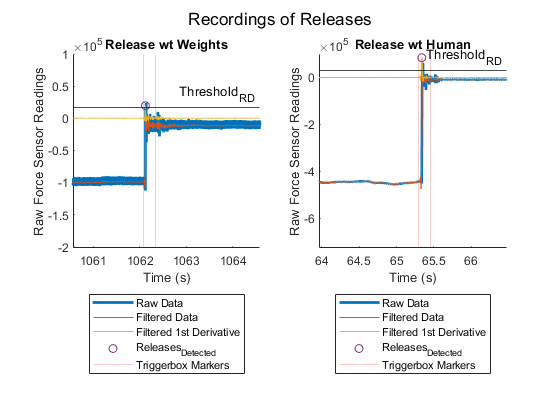

% test plot
figure
subplot(1, 2, 1)
hold on
plot(data_ActiCHamp_GUI_weights(2 : end, 1), data_ActiCHamp_GUI_weights(2 : end, 2), 'LineWidth', 2)
plot(data_ActiCHamp_GUI_weights(2 : end, 1), data_ActiCHamp_weights_filtered)
plot(timestamp_ActiCHamp_weights_derivative, data_ActiCHamp_weights_1st_derivative)
scatter(timestamp_ActiCHamp_weights_derivative(locs_GUI_weights), pks_GUI_weights)
% findpeaks(data_ActiCHamp_weights_1st_derivative)
xlabel("Time (s)")
ylabel("Raw Force Sensor Readings")
for i = 1 : length(marker_ActiCHamp_GUI_weights)
    xline(marker_ActiCHamp_GUI_weights(i), 'LineWidth', 0.5, 'Color', 'r', 'Alpha', 0.2)
end
yline(RD_minheight(1), "-k", str_threshold)
legend(str_legend, "Location", "southoutside")
hold off
xlim([1060.56 1064.59])
ylim([-202171 100000])
title("Release wt Weights")
subplot(1, 2, 2)
hold on
plot(data_ActiCHamp_GUI_humans(2 : end, 1), data_ActiCHamp_GUI_humans(2 : end, 2), 'LineWidth', 2)
plot(data_ActiCHamp_GUI_humans(2 : end, 1), data_ActiCHamp_humans_filtered)
plot(timestamp_ActiCHamp_humans_derivative, data_ActiCHamp_humans_1st_derivative)
scatter(timestamp_ActiCHamp_humans_derivative(locs_GUI_humans), pks_GUI_humans)
% findpeaks(data_ActiCHamp_humans_1st_derivative)
xlabel("Time (s)")
ylabel("Raw Force Sensor Readings")
for i = 2 : length(marker_ActiCHamp_GUI_humans)
    xline(marker_ActiCHamp_GUI_humans(i), 'LineWidth', 0.5, 'Color', 'r', 'Alpha', 0.2)
end
yline(RD_minheight(2), "-k", str_threshold)
legend(str_legend, "Location", "southoutside")
hold off
xlim([63.96 66.48])
ylim([-726303 100000])
title("Release wt Human")
sgtitle("Recordings of Releases")

The plot shown above are two releases. The left subplot is recorded with weights acting on the tether, the right subplot is recorded with Human Subjects leaning. The raw force data, the filtered force data, the derivative of the filtered force data, and the peak (release onset, indicated as the purple circle) detected are shown in each subplot. The release delay is the time difference between the left pink marker line and the purple circle.

disp(strcat("The number of detected releases (tension drops) is: ", num2str(length(locs_GUI_weights)), ", ", num2str(length(locs_GUI_humans))));

The number of detected releases (tension drops) is: 6, 9


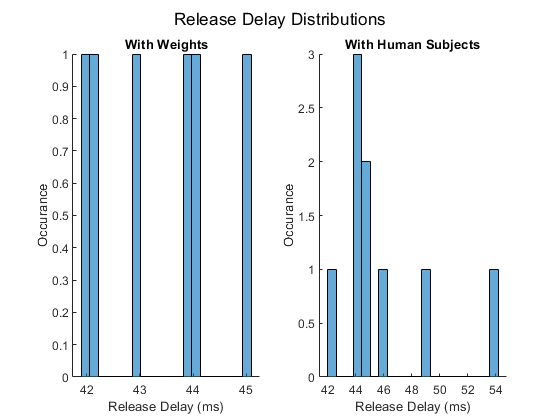

% delay calculation
release_delay_GUI_weights = zeros(length(locs_GUI_weights), 1); % initialize release delay arrays in sec
release_delay_GUI_humans = zeros(length(locs_GUI_humans), 1);
count = [1, 1]; % index for counting releases
% 2 markers for each release, 1st marker indicates button press, 2nd
% indicates button releases
press_release_flag = 1; % flag for press or release; 1 -> press, 0 -> release

for i = 2 : 2 : length(marker_ActiCHamp_GUI_weights) - 1 % only iterate through the button press, starting from 2 as the 1st marker is a dummy marker
    time_button_pressed = marker_ActiCHamp_GUI_weights(i); % obtain time of button press
    time_button_released = marker_ActiCHamp_GUI_weights(i + 1); % obtain time of button release
    time_tether_released = timestamp_ActiCHamp_weights_derivative(locs_GUI_weights((find(timestamp_ActiCHamp_weights_derivative(locs_GUI_weights) > time_button_pressed, 1))));
    % double check if the tether release is before the button release (this is usually the case)
    if time_tether_released < time_button_released
        release_delay_GUI_weights(count(1)) = time_tether_released - time_button_pressed;
        count(1) = count(1) + 1; % only iterate through the release delay array when the identified peak is associated with a trigger button press / release-event.
    end
end

for i = 2 : 2 : length(marker_ActiCHamp_GUI_humans) - 1 % only iterate through the button press, starting from 2 as the 1st marker is a dummy marker
    time_button_pressed = marker_ActiCHamp_GUI_humans(i); % obtain time of button press
    time_button_released = marker_ActiCHamp_GUI_humans(i + 1); % obtain time of button release
    time_tether_released = timestamp_ActiCHamp_humans_derivative(locs_GUI_humans((find(timestamp_ActiCHamp_humans_derivative(locs_GUI_humans) > time_button_pressed, 1))));
    % double check if the tether release is before the button release (this is usually the case)
    if time_tether_released < time_button_released
        release_delay_GUI_humans(count(2)) = time_tether_released - time_button_pressed;
        count(2) = count(2) + 1;
    end
end

% plot
figure
subplot(1, 2, 1)
hold on
histogram(release_delay_GUI_weights * 1e3, 20);
title("With Weights")
xlabel("Release Delay (ms)")
ylabel("Occurance")
hold off
subplot(1, 2, 2)
hold on
histogram(release_delay_GUI_humans * 1e3, 20);
title("With Human Subjects")
xlabel("Release Delay (ms)")
ylabel("Occurance")
hold off
sgtitle("Release Delay Distributions")

The distribution of the release delay recorded by MATLAB GUI is shown below:

pd_3 = fitdist(release_delay_GUI_humans * 1e3, "Normal")

pd_3 =   NormalDistribution

  Normal distribution
       mu = 45.8815   [43.1357, 48.6273]
    sigma =  3.5722   [2.41287, 6.84351]


**Comments:** When recording via the MATLAB GUI, the release delay has a mean value of around 45 ms with a STD of 3.6 ms. The mean release delay is about the same as the ActiCHamp release delay measured via the Lab Recorder, as shown in next section, reasons are unknown. The standard deviation of the delay is about the same as that of the release delay via the Lab Recorder. To ensure the sampling consistency and mininal influence to the sampling, the Lab Recorder will be used for the rest of the analysis.

Due to the limited number of releases here, we cannot draw meaningful conclusions yet. In the next section, we will analyze more trials recorded from the Lab Recorder.

#### Human Subject Releases (ActiCHamp, recorded via Lab Recorder)

50+ release trials on ActiCHamp and the Trigger Box system are recorded via the Lab Recorder.

% load data
channel_force = 33; % corresponds to Aux 1, there are 32 EEG channels in total
data_ActiCHamp_LAB_xdf = load_xdf(fullfile(working_folder, "AciCHamp_delay_accelerometer_force", "Exp_2.xdf")); % , 'HandleJitterRemoval', 1
marker_ActiCHamp_LAB_Release = data_ActiCHamp_LAB_xdf{1, 1}.time_stamps.'; % , cell2mat(data_ActiCHamp_LAB_Release{1, 1}.time_series.')
% note that the lab recorder stores timestamps in double but timeseries
% (sensor values) in single, when performing type conversion, do not
% convert the timestamps, only convert the timeseries by double(timeseries)
% and concatenate the timestamps.
% double(timestamps) will result in inaccurate timestamps and 0 duration
% intervals in-between timestamps.
timestamps_ActiCHamp_LAB_Release = data_ActiCHamp_LAB_xdf{1, 2}.time_stamps.';
data_ActiCHamp_LAB_Release_force = [timestamps_ActiCHamp_LAB_Release, double(data_ActiCHamp_LAB_xdf{1, 2}.time_series(channel_force, :).')];
% sort
% data_ActiCHamp_LAB_Release_force = sortrows(data_ActiCHamp_LAB_Release_force);

% Parameters
fs_nominal = 500; % nominal sampling rate 500Hz
Ts_mean = 1/fs_nominal; % mean sampling interval, nominal sampling interval from the ActiCHamp LSL program -> 500Hz -> 0.0020 s
RD_minheight = 3e4; % the release detection threshold of the force sensor readings
str_threshold = "Threshold_{RD}";
str_legend = ["Raw Data", "Filtered Data", "Filtered 1st Derivative", "Releases_{Detected}", "Triggerbox Markers"];
str_dist = ["Distribution", "Mean \mu", "\mu + 1 \sigma", "\mu - 1 \sigma"];
% display parameters
disp(strcat("The mean sampling interval of the recording is: ", num2str(Ts_mean * 1e3), " ms"));

The mean sampling interval of the recording is: 2 ms


disp(strcat("The pre-set nominal sampling rate of the Stream Connector is: ", num2str(fs_nominal), " Hz"));

The pre-set nominal sampling rate of the Stream Connector is: 500 Hz


disp(strcat("The release detection thresholds is: ", num2str(RD_minheight)));

The release detection thresholds is: 30000



% lowpass filtering to reduce noise
data_ActiCHamp_LAB_filtered = lowpass(data_ActiCHamp_LAB_Release_force(:, 2), 30, fs_nominal); % filter with pass band < 30Hz

% filtered 1st numerical derivatives
data_ActiCHamp_LAB_1st_derivative = diff(data_ActiCHamp_LAB_filtered);
% find number of release by the number of button press markers
num_button_presses = length(marker_ActiCHamp_LAB_Release) / 2; % markers are 2-marker pair (press-release)
disp(strcat("The number of recorded button presses: ", num2str(num_button_presses)));

The number of recorded button presses: 56



% peak detection and thresholding
[pks_LAB_force, locs_LAB_force] = findpeaks(data_ActiCHamp_LAB_1st_derivative, "MinPeakHeight", RD_minheight);

% delay calculation
release_delay_LAB = zeros(num_button_presses, 1); % initialize release delay arrays in sec
count = 1; % index for counting releases
% 2 markers for each release, 1st marker indicates button press, 2nd
% indicates button releases

for i = 1 : 2 : length(marker_ActiCHamp_LAB_Release) - 1 % only iterate through the button press, no dummy marker, starts from the 1st marker (press)
    time_button_pressed = marker_ActiCHamp_LAB_Release(i); % obtain time of button press
%     time_button_released = marker_ActiCHamp_LAB_Release(i + 1); % obtain time of button release
    time_tether_released = data_ActiCHamp_LAB_Release_force(locs_LAB_force((find(data_ActiCHamp_LAB_Release_force(locs_LAB_force, 1) > time_button_pressed, 1))), 1);
    % double check if the tether release is before the button release (this is usually the case)
    if time_tether_released >= time_button_pressed
        release_delay_LAB(count) = time_tether_released - time_button_pressed;
        count(1) = count + 1; % only iterate through the release delay array when the identified peak is associated with a trigger button press / release-event.
    end  
end
disp(strcat("The number of detected releases (tension drops) is: ", num2str(length(locs_LAB_force))));

The number of detected releases (tension drops) is: 56



% plot
figure
ax1 = subplot(1, 4, 1 : 3);
hold on
plot(data_ActiCHamp_LAB_Release_force(:, 1), data_ActiCHamp_LAB_Release_force(:, 2), 'LineWidth', 2)
plot(data_ActiCHamp_LAB_Release_force(:, 1), data_ActiCHamp_LAB_filtered)
plot(data_ActiCHamp_LAB_Release_force(2 : end, 1), data_ActiCHamp_LAB_1st_derivative)
scatter(data_ActiCHamp_LAB_Release_force(locs_LAB_force, 1), pks_LAB_force)
% findpeaks(data_ActiCHamp_weights_1st_derivative)
xlabel("Time (s)")
ylabel("Raw Force Sensor Readings")
for i = 1 : length(marker_ActiCHamp_LAB_Release)
    xline(marker_ActiCHamp_LAB_Release(i), 'LineWidth', 0.5, 'Color', 'r', 'Alpha', 0.2)
end
yline(RD_minheight, "-k", str_threshold)
title("Raw and Processed Data")
legend(str_legend, "Location", "southoutside")
hold off

subplot(1, 4, 4)
hold on
histogram(release_delay_LAB * 1e3, 20); % in ms
title("With Human Subjects")
xlabel("Release Delay (ms)")
ylabel("Occurance")
hold off
title("Release Delay Distributions")
sgtitle("Recordings and Distribution of Releases")
pd_LAB = fitdist(release_delay_LAB .* 1e3, 'Normal') % in ms

pd_LAB =   NormalDistribution

  Normal distribution
       mu = 43.6337   [42.9145, 44.3529]
    sigma = 2.68566   [2.26421, 3.30136]


The distribution of the release delay between the trigger button and the force sensor recorded via the Lab Recorder is shown above. The mean delay is 43.6 ms and the STD is 2.6 ms.

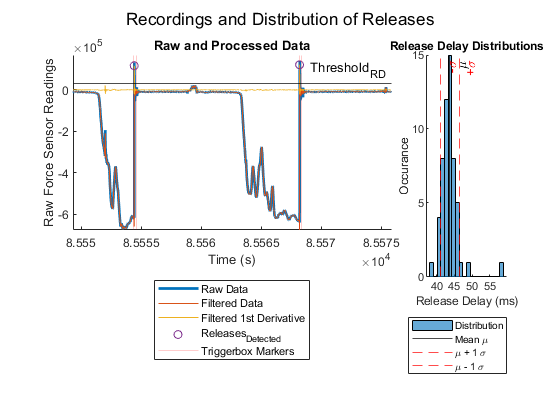

hold on
xline(pd_LAB.mu, '-k', '\mu')
xline(pd_LAB.mu + pd_LAB.sigma, '--r', '+\sigma')
xline(pd_LAB.mu - pd_LAB.sigma, '--r', '-\sigma')
hold off
legend(str_dist, "Location", "southoutside")
set(ax1, 'XLim', [85549.3 85575.8], 'YLim', [-674641 167886]); % Modify limits for first subplot

If we zoom in and show 1 perturbation, the raw data is relatively clean and the peaks are well identifiable. Only 1 peak is detected for each release trigger (red yline).

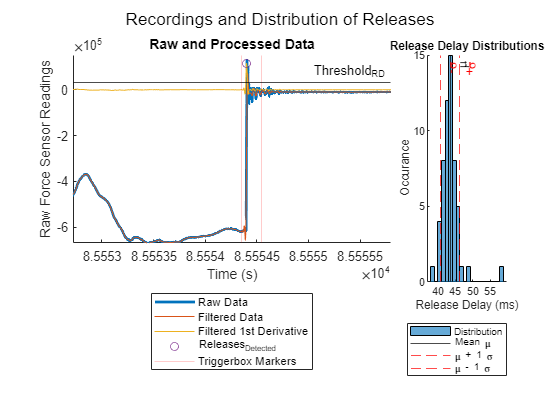

% axes 1
set(ax1, 'XLim', [85552.72 85555.80], 'YLim', [-669275 151787]); % Modify limits for first subplot

With more samples, the distribution of the release delays are shown. It is clear that the distribution roughly follows a skewed distribution? But this could also be due to the limited number of samples. 

**Comments:** Note that the Lab Recorder recorded release delays has a mean value of around 43.7 ms, about the same as the MATLAB GUI recorded release delays (mean = 45 ms). The STD of the release delays are around 2.68 ms, with a 95% confidence interval around 2.2 to 3.3 ms. The release delay is mostly normally distributed (with 1 outlier > 55 ms, not investigated, could be due to peak detection algorithm). Note that the nominal sampling interval of Lab recorder is 2 ms. So the fluctuations of the STD of release delays are within 1-2 data samples. Considering that the N1 potential is 50-150 ms after the release, the release delay between the button press and the force sensor tension drop that falls within 15.3 ms $\pm$ 3.3 ms ($\pm 1 \sigma$, 68% of cumulative probability, assuming normally distributed) should give accurate enough indicator of release.

### Conclusion

The mean delay between the trigger button press and the force sensor drop is around 44 ms with an std of 3 ms. This makes the trigger button a quite reliable indicator of the release event, considering that the N1 potential could be 50-150 ms after the release and is wide itself.

## Experiment 2b: Accelerometer vs. Load Cell (Force Sensor)

Now, we look at the accelerometer. I used ActiCHamp system for this experiment. Thus I used an external accelerometer connected the the Aux 5, 6, 7 channels to the ActiCHamp. The accelerometer is taped to the harness in front of the left chest. The orientation of the accelerometer is indicated below:

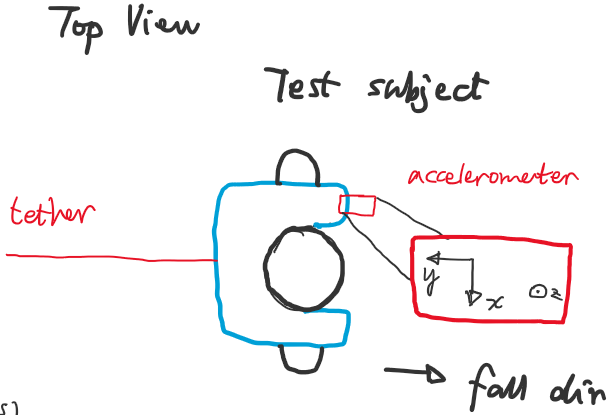

I tested the accelerometer's x, y, and z directions (Rajashree confirmed that this accelerometer is used for measuring head movement) connected to ActiCHamp. I haven't tested the on-board accelerometer orientations on LiveAmp. Signals on x, y, and z channels are all adequate to find the offset (delay). However, I am using the acceleration magnitude sqrt(x^2+y^2+z^2) for peak detection (to determine movement onset) so that the orientation of the accelerometer doesn't matter. For reference, I took notes on the ActiCHamp accelerometer orientation for the trials. We can still obtain similar delay results if we only use 1 channel.

### Analysis

#### Accelerometer Delay (ActiCHamp, recorded via Lab Recorder)

channel_acc = [37, 38, 39]; % corresponds to Aux 5, 6, 7
RD_minheight = 2e6

RD_minheight = 2000000

data_ActiCHamp_LAB_Release_acc = [timestamps_ActiCHamp_LAB_Release, double(data_ActiCHamp_LAB_xdf{1, 2}.time_series(channel_acc, :).')];
% data_ActiCHamp_LAB_Release_acc = sortrows(data_ActiCHamp_LAB_Release_acc);

str_legend = ["Raw Data", "Releases_{Detected}", "X Acceleration", "Y Acceleration", "Z Acceleration", "Acceleration Magnitude", "Releases_{Detected}", "Triggerbox Markers"];
str_dist = ["Distribution", "Mean \mu", "\mu + 1 \sigma", "\mu - 1 \sigma"];

% Preprocessing
% combine x, y, z axis geometrically to obtain the mod
x_standalone = data_ActiCHamp_LAB_Release_acc(:, 2);
y_standalone = data_ActiCHamp_LAB_Release_acc(:, 3);
z_standalone = data_ActiCHamp_LAB_Release_acc(:, 4);
acc_mag = sqrt(x_standalone.^2 + y_standalone.^2 + z_standalone.^2);
% display parameters
disp(strcat("The mean sampling interval of the recording is: ", num2str(Ts_mean * 1e3), " ms")); % in ms

The mean sampling interval of the recording is: 2 ms


disp(strcat("The pre-set nominal sampling rate of the Stream Connector is: ", num2str(fs_nominal), " Hz"));

The pre-set nominal sampling rate of the Stream Connector is: 500 Hz


disp(strcat("The release detection thresholds is: ", num2str(RD_minheight)));

The release detection thresholds is: 2000000


% lowpass filtering to reduce noise
data_ActiCHamp_LAB_filtered = lowpass(acc_mag, 30, fs_nominal); % filter with pass band < 30Hz

% find number of release by the number of button press markers
num_button_presses = length(marker_ActiCHamp_LAB_Release) / 2; % remove the 1st dummy marker, the rest markers are 2-marker pair (press-release)
disp(strcat("The number of recorded button presses: ", num2str(num_button_presses)));

The number of recorded button presses: 56



% peak detection and thresholding
[pks_LAB_acc, locs_LAB_acc] = findpeaks(data_ActiCHamp_LAB_filtered, "MinPeakHeight", RD_minheight);

% delay calculation
release_delay_LAB = zeros(num_button_presses, 1); % initialize release delay arrays in sec
count = 1; % index for counting releases
% 2 markers for each release, 1st marker indicates button press, 2nd
% indicates button releases

for i = 1 : 2 : length(marker_ActiCHamp_LAB_Release) - 1 % only iterate through the button press, starting from the 1st marker (press)
    time_button_pressed = marker_ActiCHamp_LAB_Release(i); % obtain time of button press
    time_acceleration = data_ActiCHamp_LAB_Release_acc(locs_LAB_acc(find(data_ActiCHamp_LAB_Release_acc(locs_LAB_acc, 1) > time_button_pressed, 1)), 1);
%     time_button_released = marker_ActiCHamp_LAB_Release(i + 1); % obtain time of button release
    time_tether_released = data_ActiCHamp_LAB_Release_force(locs_LAB_force(find(data_ActiCHamp_LAB_Release_force(locs_LAB_force, 1) > time_button_pressed, 1)), 1);
    % double check if the tether release is before the button release (this is usually the case)
    if time_acceleration >= time_button_pressed
        release_delay_LAB(count) = time_acceleration - time_tether_released;
        count(1) = count + 1;
    end 
end

% plot
figure;
ax2 = subplot(1, 4, 1 : 3);
hold on
plot(data_ActiCHamp_LAB_Release_force(:, 1), data_ActiCHamp_LAB_Release_force(:, 2), 'LineWidth', 2)
% plot(data_ActiCHamp_LAB_Release_force(:, 1), data_ActiCHamp_LAB_filtered)
% plot(data_ActiCHamp_LAB_Release_force(2 : end, 1), data_ActiCHamp_LAB_1st_derivative)
scatter(data_ActiCHamp_LAB_Release_force(locs_LAB_force, 1), pks_LAB_force)

plot(data_ActiCHamp_LAB_Release_acc(:, 1), x_standalone)
plot(data_ActiCHamp_LAB_Release_acc(:, 1), y_standalone)
plot(data_ActiCHamp_LAB_Release_acc(:, 1), z_standalone)
plot(data_ActiCHamp_LAB_Release_acc(:, 1), data_ActiCHamp_LAB_filtered)
scatter(data_ActiCHamp_LAB_Release_acc(locs_LAB_acc, 1), pks_LAB_acc)
xlabel("Time (s)")
ylabel("Raw Accelerometer Readings")
for i = 1 : length(marker_ActiCHamp_LAB_Release)
    xline(marker_ActiCHamp_LAB_Release(i), 'LineWidth', 0.5, 'Color', 'r', 'Alpha', 0.2)
end
yline(RD_minheight, "-k", str_threshold)
title("Raw and Processed Data")
legend(str_legend, "Location", "southoutside")
subplot(1, 4, 4)
hold on
histogram(release_delay_LAB * 1e3, 20); % in ms
title("With Human Subjects")
xlabel("Release Delay (ms)")
ylabel("Occurance")
hold off
title("Release Delay Distributions")
sgtitle("Recordings and Distribution of Releases")

pd_LAB = fitdist(release_delay_LAB * 1e3, 'Normal') % in ms

pd_LAB =   NormalDistribution

  Normal distribution
       mu =  14.5716   [14.307, 14.8363]
    sigma = 0.988256   [0.833173, 1.21482]


The accelerometer indicated release is very close to the force sensor indicated release. With a mean delay of 14.6 ms and a STD of 1.0 ms. The STD is slightly better than that of the trigger button. Actually, if we look into a few releases, we easily find out that the first acceleration magnitude peak after the trigger button press (causes by the release of tether, indicates the release event) is about 7 samples (if nominal sampling interval = 2 ms, 2 * 7 = 14 ms) after the force drop from the force sensor. And the result is farely consistent.

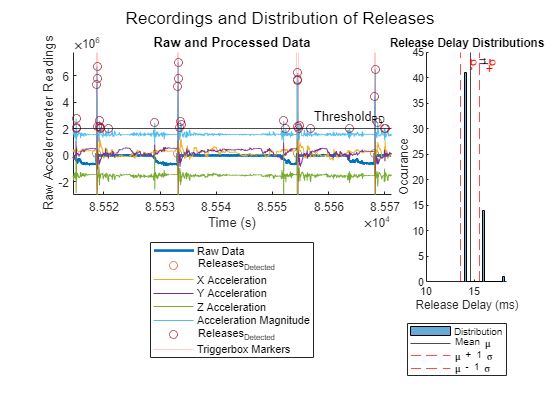

hold on
xline(pd_LAB.mu, '-k', '\mu')
xline(pd_LAB.mu + pd_LAB.sigma, '--r', '+\sigma')
xline(pd_LAB.mu - pd_LAB.sigma, '--r', '-\sigma')
hold off
legend(str_dist, "Location", "southoutside")
% axes 1
set(ax2, 'XLim', [85514.5 85571.1], 'YLim', [-2993631 7802548]); % Modify limits for first subplot

If we zoom in to show 1 release, we can identify that multiple peaks are detected for each release trigger.Multiple peaks are detected in close proximity after the release trigger (the red xline befor the first detected peak).

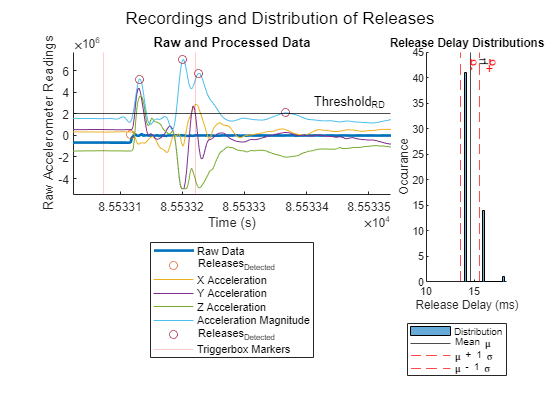

set(ax2, 'XLim', [85533.024 85533.536], 'YLim', [-5525733 7734218]); % Modify limits for first subplot

**Comments:** Looking at the distribution of the release delay of the accelerometer, we can see that 41 out of the 56 releases have an acceleration peak exactly 7 samples (14ms) after the force drop, 14 releases have the acceleration peak 8 samples after the force drop. The distribution of the acceleration peak delay proves that the accelerometer can be a very reliable indicator for the release event. Consider its ease of use, setup simplicity, and wiring, accelerometer is a even better indicator than the trigger button. However, we have to consider the multiple peaks detected after each release. We have to invest more on algorithms to accurate detect the release-related acceleration peak when given only the accelerometer data. Or we can use the trigger button marker to assist the release-related peak detection. The release-related acceleration peak is after the trigger button press and followed by a more prominant peak. The release-related acceleration peak is usually smaller in magnitude or prominance (determined by the placement of the accelerometer) when compared to the later stepping response peak as the stepping response cause a more profround impact on the subject's body. 

Here the accelerometer is attached to the harness around chest area. The accelerometer is attached with its x-y-z axis direction label facing up. The tether is aligned with the y-axis. The fall direction is on the negative y direction. Readings from this setup has shown clear and prominant peaks after each release trigger. However, multiple peaks are detected, as shown in the above zoomed in plot of the raw data that could be due to the oscillation of the harness and the attached accelerometer after the release. Only the first peak about the threshold after each release trigger is used for calculating the release delay to ensure consistency. By looking at x, y, z axis differently, we can see that the undesired oscillation comes from a combination of x, y, and z axis. The combinations of x, y, and z readings in the desired peak and the undesired peak are distinguishable. The z acceleration is positive in the desired peak and is negative in the undesired peak. However, more in-depth analysis is required for yielding a definitive conclusion or ultilizing the acceleration readings from individual axis. 

#### Accelerometer Position

The accelerometer position is also very crucial for detecting the release event onset. Here acceleration data is recorded with the accelerometer attached at different positions on the test's subject's body. 5 tethered release via (force sensor, trigger button, and accelerometer attached) ActiCHamp Connector and Lab Recorder, 1st release acc on shoulder, 2-3rd releases acc on forearm, 4-5th releases acc on chest.  There are noises in-between releases due to repositioning of the accelerometer, thus we only present the acceleration data around 1 typical release.

% load data
data_ActiCHamp_LAB_xdf = load_xdf(fullfile(working_folder, "AciCHamp_delay_accelerometer_force", "Exp_test_3.xdf"), 'HandleJitterRemoval', 1);
marker_ActiCHamp_LAB_accPos = data_ActiCHamp_LAB_xdf{1, 2}.time_stamps.';
data_ActiCHamp_LAB_accPos = [data_ActiCHamp_LAB_xdf{1, 1}.time_stamps.', double(data_ActiCHamp_LAB_xdf{1, 1}.time_series(channel_acc, :).')];
% note: do not type convert timestamps

% Parameters
RD_minheight = 2.8e6; % minimun height of the peak for peak detection
RD_prominance = 1.5e6; % minimun peak prominance for peak detection
str_legend = ["X Acceleration", "Y Acceleration", "Z Acceleration", "Acceleration Magnitude", "Releases_{Detected}", "Triggerbox Markers"];
% display parameters
disp(strcat("The mean sampling interval of the recording is: ", num2str(Ts_mean), " s"));

The mean sampling interval of the recording is: 0.002 s


disp(strcat("The pre-set nominal sampling rate of the Stream Connector is:", num2str(fs_nominal), " Hz"));

The pre-set nominal sampling rate of the Stream Connector is:500 Hz


disp(strcat("The release detection min peak height is: ", num2str(RD_minheight)));

The release detection min peak height is: 2800000


disp(strcat("The release detection peak prominance is: ", num2str(RD_prominance)));

The release detection peak prominance is: 1500000


% Preprocessing
% combine x, y, z axis geometrically to obtain the mod
accPos_x = data_ActiCHamp_LAB_accPos(:, 2);
accPos_y = data_ActiCHamp_LAB_accPos(:, 3);
accPos_z = data_ActiCHamp_LAB_accPos(:, 4);
accPos_mag = sqrt(accPos_x.^2 + accPos_y.^2 + accPos_z.^2);
% lowpass filtering to reduce noise
data_ActiCHamp_LAB_filtered = lowpass(accPos_mag, 30, fs_nominal); % filter with pass band < 30Hz

% find number of release by the number of button press markers
num_button_presses_pos = length(marker_ActiCHamp_LAB_accPos) / 2; % remove the 1st dummy marker, the rest markers are 2-marker pair (press-release)
disp(strcat("The number of recorded button presses: ", num2str(num_button_presses_pos)));

The number of recorded button presses: 5



% peak detection and thresholding
[pks_LAB_accPos, locs_LAB_accPos] = findpeaks(data_ActiCHamp_LAB_filtered, "MinPeakHeight", RD_minheight, "MinPeakProminence", RD_prominance);

% Plot
figure;
hold on
plot(data_ActiCHamp_LAB_accPos(:, 1), accPos_x)
plot(data_ActiCHamp_LAB_accPos(:, 1), accPos_y)
plot(data_ActiCHamp_LAB_accPos(:, 1), accPos_z)
plot(data_ActiCHamp_LAB_accPos(:, 1), accPos_mag)
scatter(data_ActiCHamp_LAB_accPos(locs_LAB_accPos, 1), pks_LAB_accPos)
hold off
xlabel("Time (s)")
ylabel("Raw Accelerometer Readings")
for i = 1 : length(marker_ActiCHamp_LAB_accPos)
    xline(marker_ActiCHamp_LAB_accPos(i), 'LineWidth', 0.5, 'Color', 'r', 'Alpha', 0.2)
end
yline(RD_minheight, "-k", str_threshold)
title("Raw and Processed Data")
legend(str_legend, "Location", "southoutside")

If we zoom in to the 3rd release (when the accelerometer is attached to the forearm):

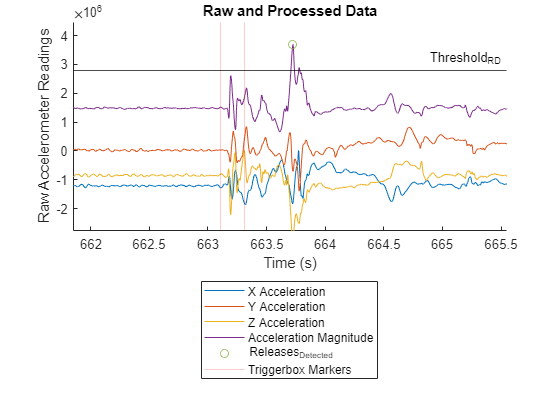

% close-up looks
xlim([661.85 665.55])
ylim([-2781137 4475537])

If we compare this release data to the previous release, we can clearly see that the amplitude of the release peak (in-between the two pink trigger button marker lines) is smaller than that when the accelerometer is attached to the shoulder/chest area. Plus, the release peak is followed by muleiple peaks. The peak detection algorithm detected the largest peak, whcih should corresponds to the impact of stepping to recover balance. 

**Comments:** The placement of the accelerometer affects the amplitude and delay of its event peaks. Generally, the more directly the accelerometer is attached to the tether (for instance, the harness vs. the shoulder), the less delay and bigger magnitude of the perturbation. The detection of release event solely on accelerometer data could unreliable when the release acceleration peaks are small in magnitude with current algorithm. A working hypothesis of the different amplitudes and delays of the accelerometer readings during the release is that the human body segments and clothes are spring damper systems that causes delay and soften the sudden impact at the moment of release. Thus, a rigid connection between the accelerometer and the harness is crucial for minimizing the delay (from the release event to the accelerometer peak detection) and maximize the amplitude of the peak (as shown in the previous section).

### Conclusion

The mean delay between the force sensor drop and the accelerometer peak is close to 14 ms with an std of 1 ms. This also makes the accelerometer a very good indicator of the release event with small delay and better reliability when compared to the trigger button (when properly placed on the subject). However, the placement of the accelerometer (in the ActiCHamp case) or the LiveAmp is crucial for resulting in a clear signal (large magnitude, large prominance) and a small delay.

### Accelerometer (LiveAmp Built-in vs. Stand-alone)

As in the previous section we concluded that the accelerometer is a good indicator of the release event when placed properly. LiveAmp has a built-in accelerometer that is very convenient but offers less flexibility in the placement when compared to a stand-alone accelerometer that can be taped almost everywhere on the test subject. Thus, we want to investigate whether the LiveAmp built-in accelerometer is sufficient for determining the release event, or a stand-alone accelerometer is necessary. In this experiment, we connected an external stand-alone accelerometer to the LiveAmp via the LiveAmp Sensors & Triggers Extention and performed 50+ releases. The results are analyzed below after determining the corresponding channels for the accelerometers.

#### LiveAmp Builtin Accelerometer Test

LiveAmp has a builtin accelerometer. However, the LSL LiveAmp connector program does not specify which channels do the accelerometer signals belong to. Thus, I record a test data with EEG electrodes hang in air and manipulate the LiveAmp in three directions. The resulted .xdf data recording contains 43 channels. There are 32 EEG and 8 AUX channels, leaving the additional channels for accelerometer. The plot below showing the raw readings from channel 41, 42, and 43, confirms that these 3 channels are for the LiveAmp onboard accelerometer.

% load data
data_LiveAmp_test_LAB_xdf = load_xdf(fullfile(working_folder, "AciCHamp_delay_accelerometer_force", "Exp_test_4.xdf"), 'HandleJitterRemoval', 1); % test data for identifying built-in accelerometer channels.
data_LiveAmp_exp_LAB_xdf = load_xdf(fullfile(working_folder, "LiveAmp_delay_accelerometer", "Exp_1.xdf"), 'HandleJitterRemoval', 1); % release data

marker_LiveAmp_LAB_Release = data_LiveAmp_exp_LAB_xdf{1, 1}.time_stamps.'; % get release trigger button markers

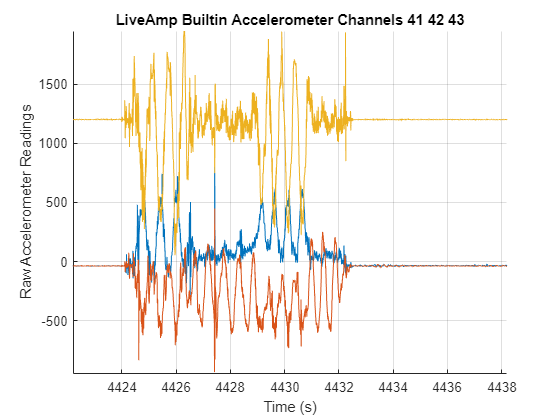

% Parameters
channel_acc_live = 41 : 43;
data_LiveAmp_test_LAB_acc = [data_LiveAmp_test_LAB_xdf{1, 3}.time_stamps.', double(data_LiveAmp_test_LAB_xdf{1, 3}.time_series(channel_acc_live, :).')];

% plot
figure
hold on
plot(data_LiveAmp_test_LAB_acc(:, 1), data_LiveAmp_test_LAB_acc(:, 2))
plot(data_LiveAmp_test_LAB_acc(:, 1), data_LiveAmp_test_LAB_acc(:, 3))
plot(data_LiveAmp_test_LAB_acc(:, 1), data_LiveAmp_test_LAB_acc(:, 4))
hold off
grid on
xlim([4422.2 4438.2])
ylim([-948 1948])
xlabel("Time (s)")
ylabel("Raw Accelerometer Readings")
title("LiveAmp Builtin Accelerometer Channels 41 42 43")

Through the above plot, we have identified that the built-in accelerometer of LiveAmp has dedicated channels 41, 42, and 43 (when configured 32 EEG channels + 8 AUX channels). The channels should correspond to x, y, and z axis. But further verification is needed to comfirm the axis-to-channel correspondance. The experiment configurations are shown below:

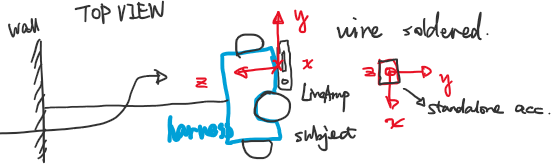

% Parameters
channel_acc_builtin = 41 : 43;
channel_acc

channel_acc =     37    38    39


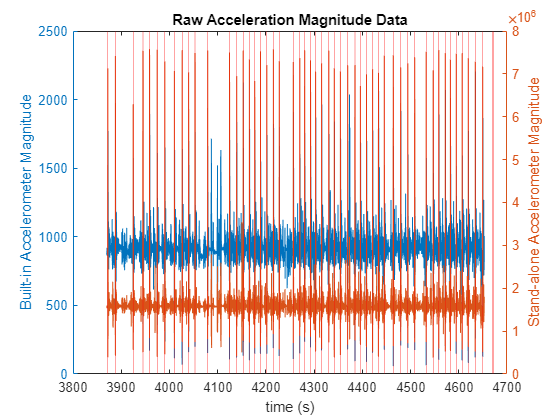

RD_minheight = [1250, 4e6];
% load data from accelerometer data from the built-in accelerometer and AUX
% accelerometer
timestamps_LiveAmp_exp_LAB = data_LiveAmp_exp_LAB_xdf{1, 3}.time_stamps.';
data_LiveAmp_exp_LAB_acc_builtin = double(data_LiveAmp_exp_LAB_xdf{1, 3}.time_series(channel_acc_builtin, :).');
data_LiveAmp_exp_LAB_acc_standalone = double(data_LiveAmp_exp_LAB_xdf{1, 3}.time_series(channel_acc, :).');


str_legend = ["Magnitude_{Built-in}", "Releases_{Built-in}", ...
    "Magnitude_{Stand-alone}", "Releases_{Stand-alone}", ...
     "Triggerbox Markers"];
str_dist = ["Distribution", "Mean \mu", "\mu + 1 \sigma", "\mu - 1 \sigma"];

% Preprocessing
% crop
sample_SOI = 11949 : 403400; % section of interest
timestamps_LiveAmp_exp_LAB = timestamps_LiveAmp_exp_LAB(sample_SOI);
data_LiveAmp_exp_LAB_acc_builtin = data_LiveAmp_exp_LAB_acc_builtin(sample_SOI, :);
data_LiveAmp_exp_LAB_acc_standalone = data_LiveAmp_exp_LAB_acc_standalone(sample_SOI, :);
% combine x, y, z axis geometrically to obtain the mod 
% for both accelerometers
x_builtin = data_LiveAmp_exp_LAB_acc_builtin(:, 1);
y_builtin = data_LiveAmp_exp_LAB_acc_builtin(:, 2);
z_builtin = data_LiveAmp_exp_LAB_acc_builtin(:, 3);
mag_builtin = sqrt(x_builtin.^2 + y_builtin.^2 + z_builtin.^2);

x_standalone = data_LiveAmp_exp_LAB_acc_standalone(:, 1);
y_standalone = data_LiveAmp_exp_LAB_acc_standalone(:, 2);
z_standalone = data_LiveAmp_exp_LAB_acc_standalone(:, 3);
mag_standalone = sqrt(x_standalone.^2 + y_standalone.^2 + z_standalone.^2);
% test plot and cut-out the irrelevent trigger button presses
figure

yyaxis left
plot(timestamps_LiveAmp_exp_LAB, mag_builtin);
ylabel("Built-in Accelerometer Magnitude")
yyaxis right
hold on
plot(timestamps_LiveAmp_exp_LAB, mag_standalone);
for i = 1 : length(marker_LiveAmp_LAB_Release)
    xline(marker_LiveAmp_LAB_Release(i), 'LineWidth', 0.5, 'Color', 'r', 'Alpha', 0.2)
end
hold off
xlabel("time (s)")
ylabel("Stand-alone Accelerometer Magnitude")
title("Raw Acceleration Magnitude Data")

% 3870s to 4652s are the section of interest [11949 : 403400]
% there are 4 undesired button press-release at the end of the recording

Based on the plot, we identify that at time from 3870s to 4652s are the section of experimental trials in the recording. We need to exclude the 4 undesired button press-release at the end as they are not associated with release events.

% display parameters
disp(strcat("The mean sampling interval of the recording is: ", num2str(Ts_mean * 1e3), " ms")); % ms

The mean sampling interval of the recording is: 2 ms


disp(strcat("The pre-set nominal sampling rate of the Stream Connector is:", num2str(fs_nominal), " Hz"));

The pre-set nominal sampling rate of the Stream Connector is:500 Hz


disp(strcat("The release detection thresholds is: ", num2str(RD_minheight)));

The release detection thresholds is: 1250  4000000



% lowpass filtering to reduce noise
mag_builtin_filtered = lowpass(mag_builtin, 30, fs_nominal);
mag_standalone_filtered = lowpass(mag_standalone, 30, fs_nominal); % filter with pass band < 30Hz


% find number of release by the number of button press markers
num_button_presses = (length(marker_LiveAmp_LAB_Release) - 4) / 2; % remove last 2 pairs of button press-release
disp(strcat("The number of recorded button presses: ", num2str(num_button_presses)));

The number of recorded button presses: 51


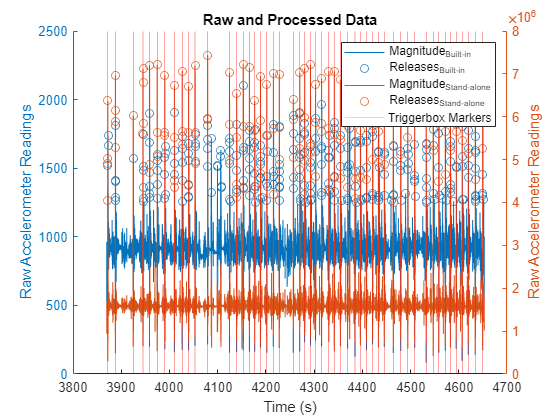


% peak detection and thresholding
[pks_builtin, locs_builtin] = findpeaks(mag_builtin_filtered, "MinPeakHeight", RD_minheight(1));
[pks_standalone, locs_standalone] = findpeaks(mag_standalone_filtered, "MinPeakHeight", RD_minheight(2));

% delay calculation
release_delay_comp = zeros(num_button_presses, 2); % initialize release delay arrays in sec

count = 1; % index for counting releases
% 2 markers for each release, 1st marker indicates button press, 2nd
% indicates button releases

for i = 1 : 2 : num_button_presses * 2 % only iterate through the button press
    time_button_pressed = marker_LiveAmp_LAB_Release(i); % obtain time of button press
    time_acceleration_builtin = timestamps_LiveAmp_exp_LAB(locs_builtin(find(timestamps_LiveAmp_exp_LAB(locs_builtin) > time_button_pressed, 1)));
    time_acceleration_standalone = timestamps_LiveAmp_exp_LAB(locs_standalone(find(timestamps_LiveAmp_exp_LAB(locs_standalone) > time_button_pressed, 1)));

    % double check if the tether release is before the button release (this is usually the case)
    release_delay_comp(count, 1) = time_acceleration_builtin - time_button_pressed;
    release_delay_comp(count, 2) = time_acceleration_standalone - time_button_pressed;
    count = count + 1;
end

% plot
figure;
hold on
% plot(timestamps_LiveAmp_exp_LAB, data_LiveAmp_exp_LAB_acc_builtin(:, 1))
% plot(timestamps_LiveAmp_exp_LAB, data_LiveAmp_exp_LAB_acc_builtin(:, 2))
% plot(timestamps_LiveAmp_exp_LAB, data_LiveAmp_exp_LAB_acc_builtin(:, 3))
yyaxis left
plot(timestamps_LiveAmp_exp_LAB, mag_builtin_filtered)
scatter(timestamps_LiveAmp_exp_LAB(locs_builtin), pks_builtin)
ylabel("Raw Accelerometer Readings")
% plot(timestamps_LiveAmp_exp_LAB, data_LiveAmp_exp_LAB_acc_standalone(:, 1))
% plot(timestamps_LiveAmp_exp_LAB, data_LiveAmp_exp_LAB_acc_standalone(:, 2))
% plot(timestamps_LiveAmp_exp_LAB, data_LiveAmp_exp_LAB_acc_standalone(:, 3))
yyaxis right
plot(timestamps_LiveAmp_exp_LAB, mag_standalone_filtered)
scatter(timestamps_LiveAmp_exp_LAB(locs_standalone), pks_standalone)
xlabel("Time (s)")
ylabel("Raw Accelerometer Readings")
for i = 1 : length(marker_LiveAmp_LAB_Release) - 4
    xline(marker_LiveAmp_LAB_Release(i), 'LineWidth', 0.5, 'Color', 'r', 'Alpha', 0.2)
end
% yline(RD_minheight, "-k", str_threshold)
title("Raw and Processed Data")
legend(str_legend)

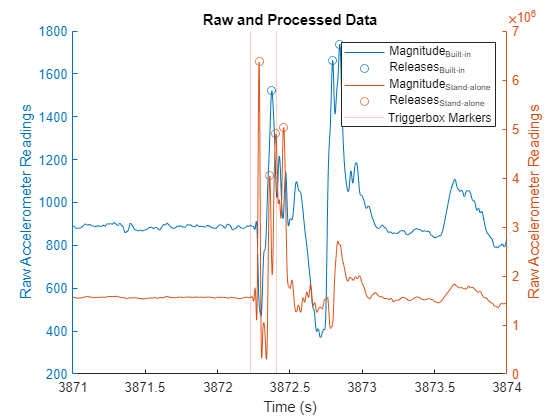

xlim([3871 3874])

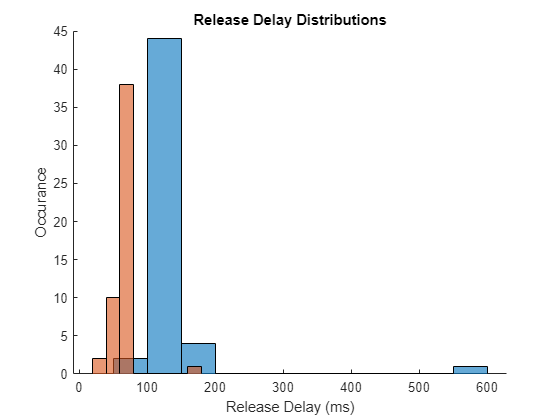

figure
hold on
histogram(release_delay_comp(:, 1) * 1e3); % in ms
histogram(release_delay_comp(:, 2) * 1e3);
title("Release Delay Distributions")
xlabel("Release Delay (ms)")
ylabel("Occurance")
hold off
title("Release Delay Distributions")


pd_LAB = fitdist(release_delay_comp(:, 2) * 1e3, 'Normal') % in ms

pd_LAB =   NormalDistribution

  Normal distribution
       mu = 62.0492   [57.3019, 66.7966]
    sigma = 16.8792   [14.123, 20.9822]
